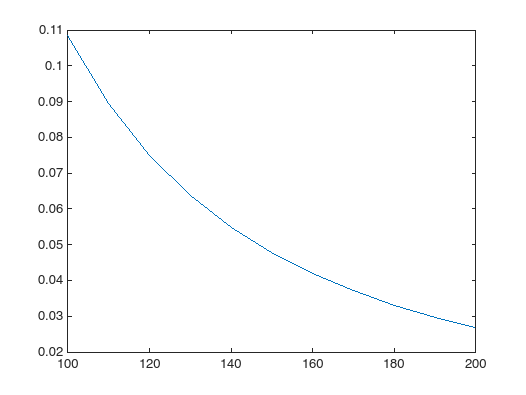

syms f(x)

f(x) = (x^2 - x)*(sin(x) + cos(x))/10;

startX = 0;

endX = 20;

minN = 100;
stepN = 10;
maxN = 200;


miniStep = 0.001;


devs = zeros(1, (maxN-minN)/stepN + 1);

for curN = minN:stepN:maxN

    X = linspace(startX, endX, curN);

    Y = double(f(X));

    x = startX:miniStep:endX;

    y = spline0Values(X, Y, x);

    true_y = double(f(x));

    maxDeviation = 0;

    for i = 1:length(y)
        curDeviation = abs(y(i) - true_y(i));
        if curDeviation > maxDeviation
            maxDeviation = curDeviation;
        end
    end

    devs((curN - minN)/stepN + 1) = maxDeviation;
end

plot(minN:stepN:maxN, devs)